clear
c = 299792458;

## Lorentz model


$$n^2 \left(\lambda \right)=\epsilon +\frac{\epsilon_{\textrm{Lorentz}} \omega_0^2 }{\omega_0^2 -2i\delta_0 2\pi \frac{c}{\lambda }-{\left(2\pi \frac{c}{\lambda }\right)}^2 \;}$$


## Silicon

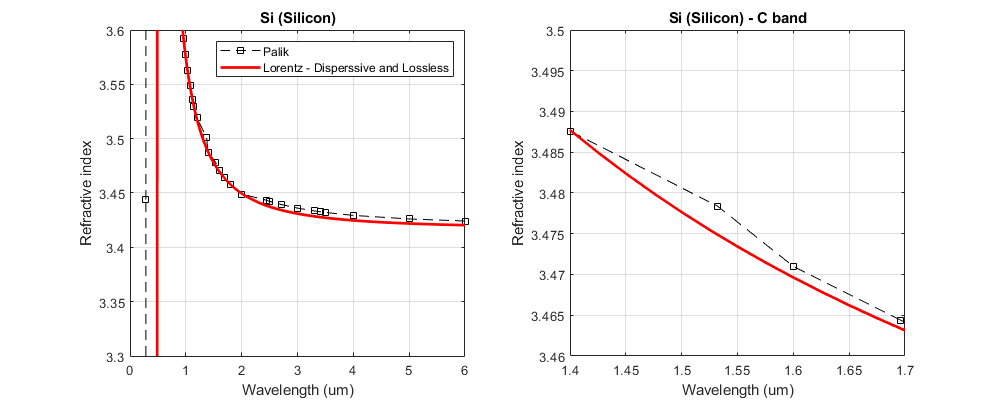

load("materials/si_palik.mat"); % si_palik

% Lorentz model
permittivity = 7.98737492;
lorentz_linewidth = 1e8;
lorentz_resonance = 3.93282466e15;
lorentz_permittivity = 3.68799143;

wavelength = si_palik.wavelength_um*1e-6;
wavelength = linspace(wavelength(1),wavelength(end),10000);
wavelength_um = wavelength/1e-6;

omega = 2*pi*c./wavelength;
lorentz_denominador = lorentz_resonance^2 - 2*1i*lorentz_linewidth*omega - (omega).^2;

n_lorentz_2 = permittivity + (lorentz_permittivity*lorentz_resonance^2)./lorentz_denominador;
n_lorentz = sqrt(n_lorentz_2);

n_lorentz_real = real(n_lorentz);

figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
plot(si_palik.wavelength_um,si_palik.index,'--sk'); hold on
plot(wavelength_um,n_lorentz_real,'r','LineWidth',2);
xlabel('Wavelength (um)');
ylabel('Refractive index');
title('Si (Silicon)')
legend('Palik','Lorentz - Disperssive and Lossless');
grid on;
ylim([3.3 3.6]);
xlim([0 6]);

subplot(1,2,2);
plot(si_palik.wavelength_um,si_palik.index,'--sk'); hold on
plot(wavelength_um,n_lorentz_real,'r','LineWidth',2);
xlabel('Wavelength (um)');
ylabel('Refractive index');
title('Si (Silicon) - C band')
grid on;
xlim([1.4 1.7]);
ylim([3.46 3.5]);

## Silicon Oxide

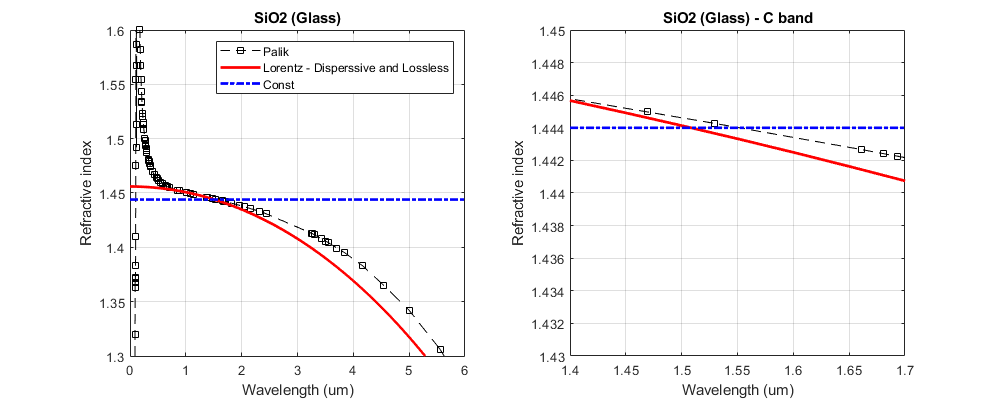

load("materials/sio2_palik.mat"); % sio2_palik

% Lorentz model
permittivity = 2.119881;
lorentz_linewidth = 1e10;
lorentz_resonance = 3.309238e13;
lorentz_permittivity = 49.43721;

wavelength = sio2_palik.wavelength_um*1e-6;
wavelength = linspace(wavelength(1),wavelength(end),10000);
wavelength_um = wavelength/1e-6;

omega = 2*pi*c./wavelength;
lorentz_denominador = lorentz_resonance^2 - 2*1i*lorentz_linewidth*omega - (omega).^2;

n_lorentz_2 = permittivity + (lorentz_permittivity*lorentz_resonance^2)./lorentz_denominador;
n_lorentz = sqrt(n_lorentz_2);

n_lorentz_real = real(n_lorentz);

figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
plot(sio2_palik.wavelength_um,sio2_palik.index,'--sk'); hold on
plot(wavelength_um,n_lorentz_real,'r','LineWidth',2);
plot([0 6],[1.444 1.444],'-.b','LineWidth',2);
xlabel('Wavelength (um)');
ylabel('Refractive index');
title('SiO2 (Glass)')
legend('Palik','Lorentz - Disperssive and Lossless','Const');
grid on;
ylim([1.3 1.6]);
xlim([0 6]);

subplot(1,2,2);
plot(sio2_palik.wavelength_um,sio2_palik.index,'--sk'); hold on
plot(wavelength_um,n_lorentz_real,'r','LineWidth',2);
plot([0 6],[1.444 1.444],'-.b','LineWidth',2);
xlabel('Wavelength (um)');
ylabel('Refractive index');
title('SiO2 (Glass) - C band')
grid on;
xlim([1.4 1.7]);
ylim([1.43 1.45]);

## Silicon Nitride

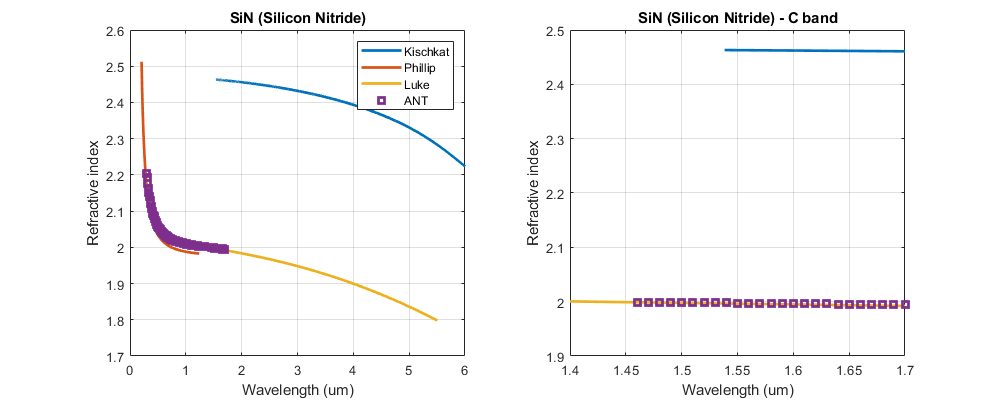

load("materials/sin_luke.mat");    % sin_luke
load("materials/sin_phillip.mat"); % sin_phillip
load("materials/sin_kischkat.mat");% sin_kischkat
load("materials/sin_ant.mat");     % sin_ant

figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
plot(sin_kischkat.wavelength_um,sin_kischkat.index,'LineWidth',2); hold on
plot(sin_phillip.wavelength_um,sin_phillip.index,'LineWidth',2);
plot(sin_luke.wavelength_um,sin_luke.index,'LineWidth',2);
plot(sin_ant.wavelength_um,sin_ant.index,'s','LineWidth',2);
xlabel('Wavelength (um)');
ylabel('Refractive index');
title('SiN (Silicon Nitride)')
legend('Kischkat','Phillip','Luke','ANT');
grid on;
xlim([0 6]);

subplot(1,2,2);
plot(sin_kischkat.wavelength_um,sin_kischkat.index,'LineWidth',2); hold on
plot(sin_phillip.wavelength_um,sin_phillip.index,'LineWidth',2);
plot(sin_luke.wavelength_um,sin_luke.index,'LineWidth',2);
plot(sin_ant.wavelength_um,sin_ant.index,'s','LineWidth',2);
xlabel('Wavelength (um)');
ylabel('Refractive index');
title('SiN (Silicon Nitride) - C band')
grid on;
xlim([1.4 1.7]);

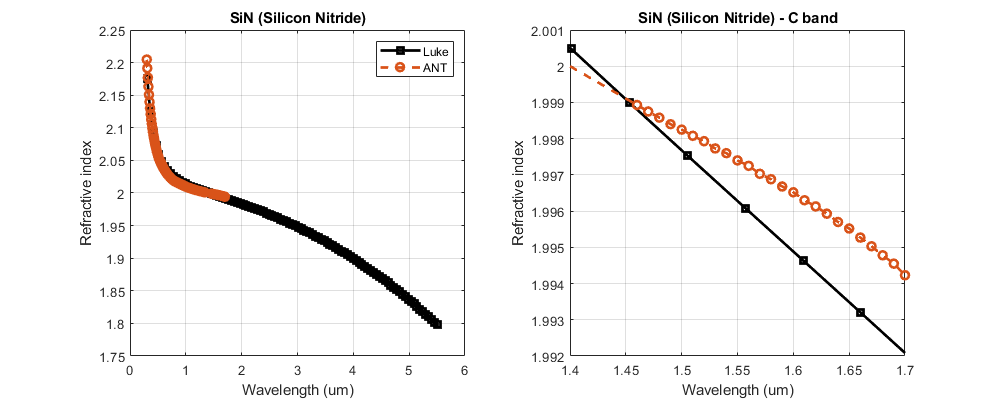


% without phillip and without kischkat
figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
plot(sin_luke.wavelength_um,sin_luke.index,'-sk','LineWidth',2); hold on
plot(sin_ant.wavelength_um,sin_ant.index,'--o','LineWidth',2);
xlabel('Wavelength (um)');
ylabel('Refractive index');
title('SiN (Silicon Nitride)')
legend('Luke','ANT');
grid on;
xlim([0 6]);

subplot(1,2,2);
plot(sin_luke.wavelength_um,sin_luke.index,'-sk','LineWidth',2); hold on
plot(sin_ant.wavelength_um,sin_ant.index,'--o','LineWidth',2);
xlabel('Wavelength (um)');
ylabel('Refractive index');
title('SiN (Silicon Nitride) - C band')
grid on;
xlim([1.4 1.7]);

### Sellmeier model of refractive index


$$n^2(\lambda) = 1 + \frac{B_1\lambda^2}{\lambda^2-C_1}+\frac{B_2\lambda^2}{\lambda^2-C_2}+\frac{B_3\lambda^2}{\lambda^2-C_3}$$


% Sellmeier model
% Initial guess for the parameters [b1, c1, b2, c2, b3, c3]
initial_params = [3.03844310, 0.01776047, 40314.3064, 1644699.9994, -0.06354214, -6.96744303];

% Set options for lsqcurvefit
options = optimoptions('lsqcurvefit', 'Display', 'iter','FunctionTolerance',1e-9);

% Perform the fit
[params_fit, resnorm] = lsqcurvefit(@Sellmeier, initial_params, sin_luke.wavelength_um, sin_luke.index,...
    [3.03844310, 0.01776047, 40314.3064, 1644699.9994, -0.06354214, -6.96744303],...
    [3.03844310, 0.01776047, 40314.3064, 1644699.9994, -0.06354214, -6.96744303], options);


Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



% Display the fitted parameters
disp('Fitted parameters:');

Fitted parameters:


disp(params_fit);

   1.0e+06 *

    0.0000    0.0000    0.0403    1.6447   -0.0000   -0.0000



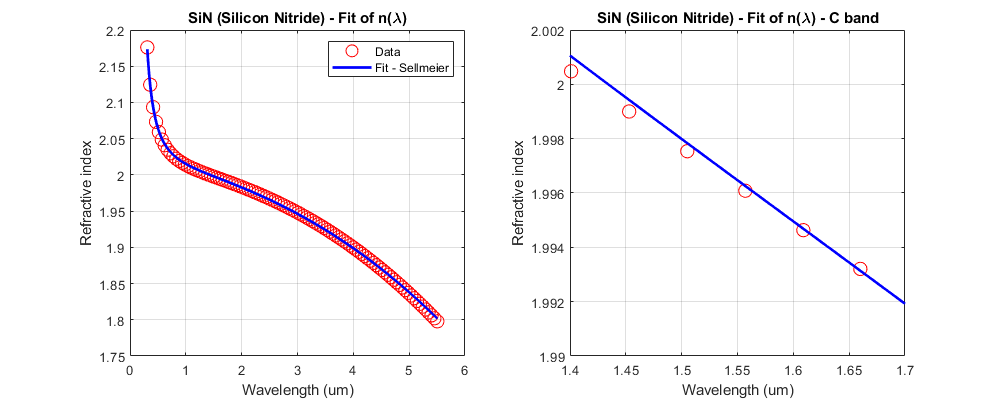


% Plot the fit
lambda_fit = linspace(min(sin_luke.wavelength_um), max(sin_luke.wavelength_um), 1000);
n_fit = Sellmeier(params_fit, lambda_fit);

figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
plot(sin_luke.wavelength_um, sin_luke.index, 'ro', 'MarkerSize', 10, 'DisplayName', 'Data');
hold on;
plot(lambda_fit, n_fit, 'b-', 'LineWidth', 2, 'DisplayName', 'Fit - Sellmeier');
xlabel('Wavelength (um)');
ylabel('Refractive index');
legend;
grid on;
title('SiN (Silicon Nitride) - Fit of n(\lambda)');

subplot(1,2,2);
plot(sin_luke.wavelength_um, sin_luke.index, 'ro', 'MarkerSize', 10, 'DisplayName', 'Data');
hold on;
plot(lambda_fit, n_fit, 'b-', 'LineWidth', 2, 'DisplayName', 'Fit - Sellmeier');
xlabel('Wavelength (um)');
ylabel('Refractive index');
xlim([1.4 1.7]);
grid on;
title('SiN (Silicon Nitride) - Fit of n(\lambda) - C band');


fprintf('Silicon Nitride: Parameters for Sellmeier')

Silicon Nitride: Parameters for Sellmeier

fprintf('-------------------------------------------------------------------------------------------------------------------------------------------------')

-------------------------------------------------------------------------------------------------------------------------------------------------

fprintf('| Parameter \t| value \t| units \t|')

| Parameter 	| value 	| units 	|

fprintf('-------------------------------------------------------------------------------------------------------------------------------------------------')

-------------------------------------------------------------------------------------------------------------------------------------------------

fprintf('|\t B1 \t| %12.8f \t|  \t\t|', params_fit(1))

|	 B1 	|   3.03844310 	|  		|

fprintf('|\t C1 \t| %12.8f \t|\t  um^2\t|', params_fit(2))

|	 C1 	|   0.01776047 	|	  um^2	|

fprintf('|\t B2 \t| %12.4f \t|  \t\t|', params_fit(3))

|	 B2 	|   40314.3064 	|  		|

fprintf('|\t C2 \t| %12.4f \t|\t  um^2\t|', params_fit(4))

|	 C2 	| 1644699.9994 	|	  um^2	|

fprintf('|\t B3 \t| %12.8f \t|  \t\t|', params_fit(5))

|	 B3 	|  -0.06354214 	|  		|

fprintf('|\t C3 \t| %12.8f \t|\t  um^2\t|', params_fit(6))

|	 C3 	|  -6.96744303 	|	  um^2	|

fprintf('-------------------------------------------------------------------------------------------------------------------------------------------------')

-------------------------------------------------------------------------------------------------------------------------------------------------

function n = Lorentz(params, lambda)
    epsilon = params(1);
    epsilon_Lorentz = params(2);
    omega_0 = params(3);
    delta_0 = params(4);
    c = 3e8; % Speed of light in vacuum (m/s)

    term1 = omega_0^2;
    term2 = 2i * delta_0 * 2 * pi * c ./ lambda;
    term3 = (2 * pi * c ./ lambda).^2;

    n = sqrt(epsilon + (epsilon_Lorentz * term1) ./ (term1 - term2 - term3));
end

function n = Sellmeier(params, lambda_um)
    b1 = params(1);
    c1 = params(2);
    b2 = params(3);
    c2 = params(4);
    b3 = params(5);
    c3 = params(6);
    
    term1 = b1*(lambda_um.^2)./(lambda_um.^2-c1);
    term2 = b2*(lambda_um.^2)./(lambda_um.^2-c2);
    term3 = b3*(lambda_um.^2)./(lambda_um.^2-c3);
    
    n = sqrt(1 + term1 + term2 + term3);
end

